# SINDy model selection: how to select / tune hyperparameter(s)

- k-fold cross-validation: [Brunton et al. 2016](https://www.pnas.org/doi/abs/10.1073/pnas.1517384113)

- Akaike information criteria: [Mangan et al 2017](https://royalsocietypublishing.org/doi/full/10.1098/rspa.2017.0009)

- Stability selection: [Maddu et al 2022](https://royalsocietypublishing.org/doi/full/10.1098/rspa.2021.0916)

## Generate Data: Lorenz system

addpath(genpath(pwd))

param = [10; 28; 8/3]; % Lorenz's parameters (chaotic)
n = 3; % number of states
x0 = [-8; 8; 27];  % Initial condition
dt = 0.001; % time step
tspan = dt:dt:20; 
options = odeset('RelTol',1e-12,'AbsTol',1e-12*ones(1,3));
[t,xClean]=ode45(@(t,x) lorenz(t,x,param),tspan,x0,options);

% Add Gaussian white noise
rng(1)
sig = 0.01; 
x = xClean + sig*std(xClean(:))*randn(size(xClean)); 


## Compute Derivative: finite difference

dx = (1/(12*dt))*(-x(5:end,:)+8*x(4:end-1,:)-8*x(2:end-3,:)+x(1:end-4,:)); % fourth order central difference

x = x(3:end-2,:); % cut tails
t = t(3:end-2,:);


## Pool Data (i.e., build library of nonlinear time series)

polyorder = 3; % polynomials up to order 3
Theta = poolData(x,n,polyorder);
m = size(Theta,2); % size of library


## SINDy-path: sweep over lambda, starting from LS solution ($\lambda =0$)

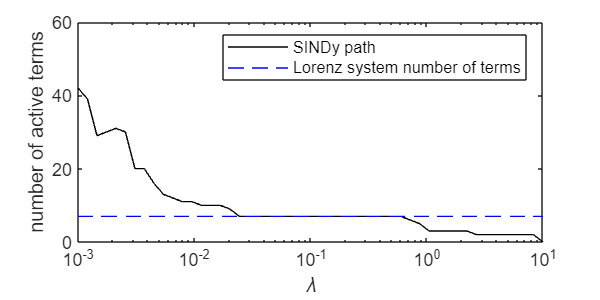

lambda = [0,logspace(-3,1,50)]; % lambda sweep: 50 steps between 10^-3:10^0
plotLambda(Theta,dx,lambda,n,m) 

# k-fold cross-validation

nl = 15; % number of lambdas to sweep through
lambda = logspace(1,-3,nl);

% k test and training partitions of data for cross validation
k = 10; % 10 fold cross validation
nT = length(Theta);
rng(1)
cvp = cvpartition(nT,'KFold',k); 

% k: run SINDy k-times on different training data partitions and calculate MSE on test data partitions
% nl: sweep over lambda
% h: number of states
Xi = zeros(size(Theta,2),n,nl,k);
epsilon = zeros(n,nl,k);
for j = 1:k
    for i = 1:nl 
        % Identify SINDy model on training data 
        Xi(:,:,i,j) = sparsifyDynamics(Theta(cvp.training(j),:), dx(cvp.training(j),:), lambda(i), n);     % sparsify library
        for h = 1:n
            % MSE on testing data
            epsilon(h,i,j) = 1/nT*sum((Theta(cvp.test(j),:)*Xi(:,h,i,j) - dx(cvp.test(j),h)).^2); 
        end 
    end
end

% calculate minimum CV score
epsilonLambda = zeros(nl,n);
for i = 1:n
    epsilonLambda(:,i) = mean(squeeze(epsilon(i,:,:)),2);
end
[~,minCV]=min(mean(epsilonLambda,2));
lambda_CV = lambda(minCV)

lambda_CV = 0.3728

% final SINDy model at min CV lambda
Xi_CV = sparsifyDynamics(Theta, dx, lambda(minCV), n)

Xi_CV =          0         0         0
   -9.9810   27.8203         0
    9.9855   -0.9457         0
         0         0   -2.6649
         0         0         0
         0         0    0.9992
         0   -0.9958         0
         0         0         0
         0         0         0
         0         0         0


### Plot $\textrm{MSE}=||\dot{\mathbf{x}} -\Theta \;\left(\mathbf{X}\right)\xi ||_2^2$ and model coefficeints $\xi \;$over $\lambda$-path

x-axis left: SINDy model with low complexity and high error 

x-axis right: model with high complexity and low error (potentially overfitting)

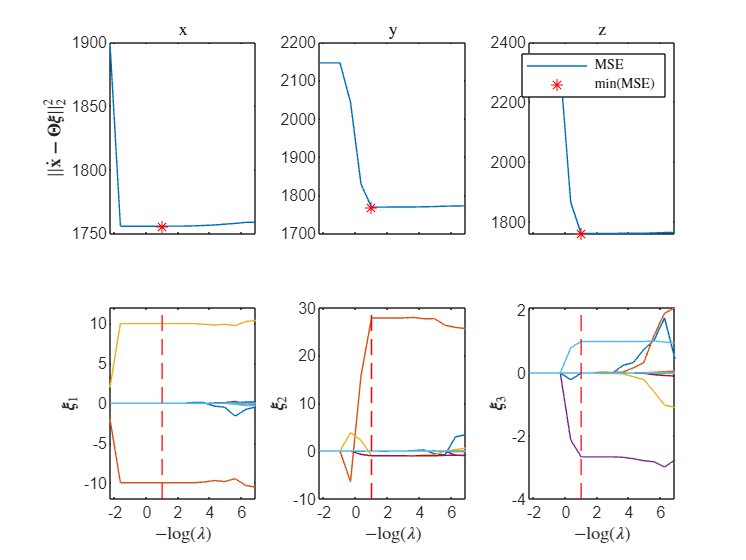

plotCV(Xi,epsilon,lambda,minCV,n)

# Akaike Information Criteria

% number of lambdas (models with different complexity) to sweep through
nl = 15; 
lambda = logspace(1,-3,nl);

% identify SINDy models with different complexity 
XiAIC = [];
for i = 1:nl 
    XiAIC(:,:,i) = sparsifyDynamics(Theta,dx,lambda(i),n); 
end

% randomly select nm initial conditions from time series data
nm = 10; % number of initial conditions for prediction 
tF = 0.2; % model prediction time span
tspanE = dt:dt:tF; 
ltE = length(tspanE)-1; % time steps model prediction
lt = round(length(x)-tF*dt); % total model prediction time - length pred time: needed for compariosn
rng(1)
x0i = randperm(lt-ltE,nm); % random selection of initial conditions
x0e = x(x0i,:); % random initial cond

% run model predictions from different initial conditions using
k = zeros(nl,1);
logL = zeros(nl,1);
aic = zeros(nl,1);
eps = zeros(nl,nm);
for i = 1:nl
    for j = 1:nm
        paramSINDy.Xi = XiAIC(:,:,i);
        paramSINDy.polyorder = polyorder;
        % integrate SINDy model
        [tSINDy,xSINDy]=ode45(@(t,x) SINDyODE(t,x,paramSINDy),tspanE,x0e(j,:),options);
        % absolute model prediction error
        eps(i,j) = sum(sum(abs(xSINDy-x(x0i(j):x0i(j)+ltE,:))))/n/ltE; 
    end
    k(i) = sum(sum(XiAIC(:,:,i)~=0)); % number of active terms
    logL(i) = nm*log(eps(i,:)*eps(i,:)'/nm); % log square abs error
    aic(i) = logL(i) + 2*k(i); % Akaike Information Criteria
end


### Plot information path: AIC over $\lambda$

x-axis left: SINDy model with low complexity and high error 

x-axis right: model with high complexity and low error (potentially overfitting)

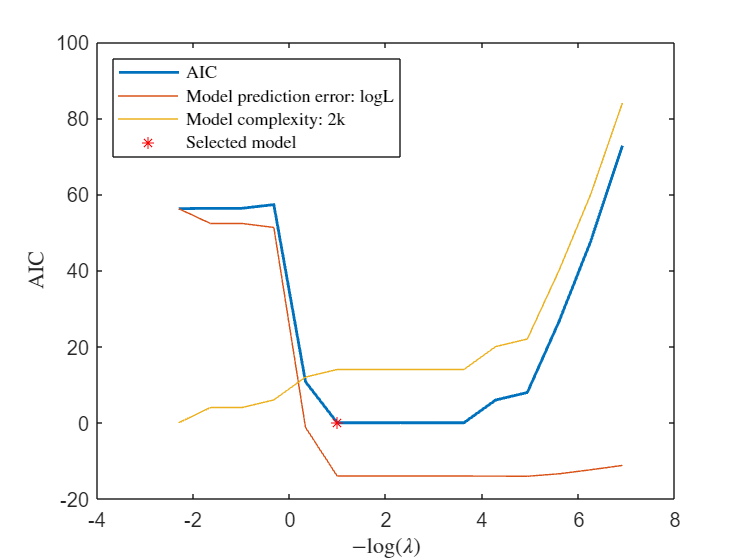

plotAIC(aic,logL,k,lambda)


% calculate minimum CV score
[~,minAIC] = min(aic);

% final SINDy model at min AIC lambda
Xi_AIC = sparsifyDynamics(Theta, dx, lambda(minAIC), n)

Xi_AIC =          0         0         0
   -9.9810   27.8203         0
    9.9855   -0.9457         0
         0         0   -2.6649
         0         0         0
         0         0    0.9992
         0   -0.9958         0
         0         0         0
         0         0         0
         0         0         0


# Stability selection

% add less noise to better visualize method
sig = 0.001; 
rng(1)
x = xClean + sig*std(xClean(:))*randn(size(xClean)); 
dx = (1/(12*dt))*(-x(5:end,:)+8*x(4:end-1,:)-8*x(2:end-3,:)+x(1:end-4,:)); % fourth order central difference
x = x(3:end-2,:); 
Theta = poolData(x,n,polyorder);

% number of lambdas (models with different complexity) to sweep through
nl = 15; 
lambda = logspace(1,-3,nl);

nT = length(Theta)/2; % N/2 -> size of subsamples: 1/2 number of measurements 

B = 50; % number of models subsamples without replacement (Maddu et al, B=250)
rng(1)
s = RandStream('mlfg6331_64');
XiSS = zeros(size(Theta,2),n,nl,B);
XiSSE = zeros(size(Theta,2),n,nl,B);

% subsample data
for j = 1:B
    dataB(:,:,j) = datasample(s,[Theta,dx],round(nT),1,'Replace',false); 
end

% for all subsamples:
% sweep over model complexity and store model structure (# active terms)
for j = 1:B
    for i = 1:nl 
        data = dataB(:,:,j);
        XiSS(:,:,i,j) = sparsifyDynamics(data(:,1:m), data(:,m+1:end), lambda(i), n); % SINDy on subsample
        XiSSE(:,:,i,j) = XiSS(:,:,i,j)~=0; % active terms
    end
end


### Plot stability path: stability over $\lambda$

x-axis left: SINDy model with low complexity and high error 

x-axis right: model with high complexity and low error (potentially overfitting)

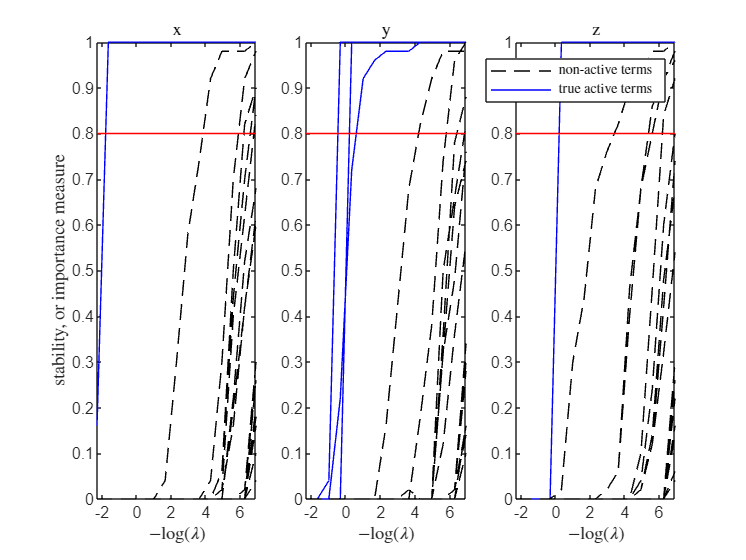

plotSS(XiSSE,lambda,m,n)

### Solve least squares on stable support

% Visual inspection of stability paths -> e.g. -log(lambda) approx 1
lambdaSS = exp(-1)

lambdaSS = 0.3679

[~,minSS]=min(abs(lambda-lambdaSS));

% select stable support
XiEM = squeeze(mean(XiSSE,4)); % inclusion probability   
disp('Stable support: inlcusion probabilities')

Stable support: inlcusion probabilities


XiSSEm = squeeze(XiEM(:,:,minSS)) 

XiSSEm =          0         0    0.3000
    1.0000    1.0000         0
    1.0000    0.9200         0
         0         0    1.0000
         0         0         0
         0         0    1.0000
         0    1.0000         0
         0         0         0
         0         0         0
         0         0         0



% solve least squares on stable support
sStable = 0.8;
XiSS = zeros(m,n);
XiSS(XiSSEm(:,1)>sStable,1) = Theta(:,XiSSEm(:,1)>sStable)\dx(:,1);
XiSS(XiSSEm(:,2)>sStable,2) = Theta(:,XiSSEm(:,2)>sStable)\dx(:,2);
XiSS(XiSSEm(:,3)>sStable,3) = Theta(:,XiSSEm(:,3)>sStable)\dx(:,3);

disp('Stability Selection SINDy model')

Stability Selection SINDy model


XiSS

XiSS =          0         0         0
  -10.0000   27.9947         0
   10.0002   -0.9986         0
         0         0   -2.6666
         0         0         0
         0         0    1.0000
         0   -0.9999         0
         0         0         0
         0         0         0
         0         0         0
